clc,clear,close all
% 读取数据

**数据获取网址：**[https://archive.ics.uci.edu/dataset/27/credit+approval](https://archive.ics.uci.edu/dataset/27/credit+approval)

**特征及标签数值类型：**

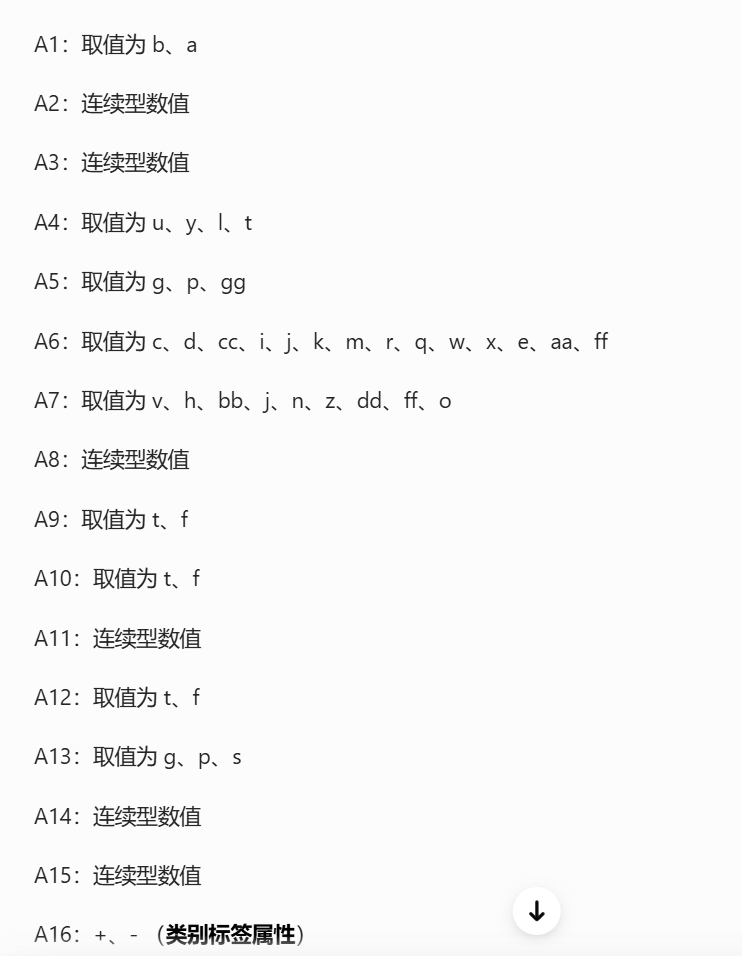

% 把整个文件读取成单元格数组，原样保留原来的内容
raw = readcell('crx.data','FileType','text')

raw = 690×16 cell 数组
    {'b'}    {[30.8300]}    {[      0]}    {'u'}    {'g'}    {'w' }    {'v'}    {[1.2500]}    {'t'}    {'t'}    {[ 1]}    {'f'}    {'g'}    {[202]}    {[    0]}    {'+'}
    {'a'}    {[58.6700]}    {[ 4.4600]}    {'u'}    {'g'}    {'q' }    {'h'}    {[3.0400]}    {'t'}    {'t'}    {[ 6]}    {'f'}    {'g'}    {[ 43]}    {[  560]}    {'+'}
    {'a'}    {[24.5000]}    {[ 0.5000]}    {'u'}    {'g'}    {'q' }    {'h'}    {[1.5000]}    {'t'}    {'f'}    {[ 0]}    {'f'}    {'g'}    {[280]}    {[  824]}    {'+'}
    {'b'}    {[27.8300]}    {[ 1.5400]}    {'u'}    {'g'}    {'w' }    {'v'}    {[3.7500]}    {'t'}    {'t'}    {[ 5]}    {'t'}    {'g'}    {[100]}    {[    3]}    {'+'}
    {'b'}    {[20.1700]}    {[ 5.6250]}    {'u'}    {'g'}    {'w' }    {'v'}    {[1.7100]}    {'t'}    {'f'}    {[ 0]}    {'f'}    {'s'}    {[120]}    {[    0]}    {'+'}
    {'b'}    {[32.0800]}    {[      4]}    {'u'}    {'g'}    {'m' }    {'v'}    {[2.5000]}    {'t'}    {'f'}    {[ 0]}    {'t'}  

% 识别缺失值并将缺失值？替换为NaN 
raw(strcmp(raw,'?'))={NaN}  % 84行

raw = 690×16 cell 数组
    {'b'}    {[30.8300]}    {[      0]}    {'u'}    {'g'}    {'w' }    {'v'}    {[1.2500]}    {'t'}    {'t'}    {[ 1]}    {'f'}    {'g'}    {[202]}    {[    0]}    {'+'}
    {'a'}    {[58.6700]}    {[ 4.4600]}    {'u'}    {'g'}    {'q' }    {'h'}    {[3.0400]}    {'t'}    {'t'}    {[ 6]}    {'f'}    {'g'}    {[ 43]}    {[  560]}    {'+'}
    {'a'}    {[24.5000]}    {[ 0.5000]}    {'u'}    {'g'}    {'q' }    {'h'}    {[1.5000]}    {'t'}    {'f'}    {[ 0]}    {'f'}    {'g'}    {[280]}    {[  824]}    {'+'}
    {'b'}    {[27.8300]}    {[ 1.5400]}    {'u'}    {'g'}    {'w' }    {'v'}    {[3.7500]}    {'t'}    {'t'}    {[ 5]}    {'t'}    {'g'}    {[100]}    {[    3]}    {'+'}
    {'b'}    {[20.1700]}    {[ 5.6250]}    {'u'}    {'g'}    {'w' }    {'v'}    {[1.7100]}    {'t'}    {'f'}    {[ 0]}    {'f'}    {'s'}    {[120]}    {[    0]}    {'+'}
    {'b'}    {[32.0800]}    {[      4]}    {'u'}    {'g'}    {'m' }    {'v'}    {[2.5000]}    {'t'}    {'f'}    {[ 0]}    {'t'}  

% 转化成表格
data = cell2table(raw)

data = 690×16 table
    raw1    raw2      raw3     raw4    raw5      raw6     raw7     raw8     raw9     raw10    raw11    raw12    raw13    raw14    raw15    raw16
    ____    _____    ______    ____    _____    ______    _____    _____    _____    _____    _____    _____    _____    _____    _____    _____

     b      30.83         0     u      {'g'}    {'w' }    {'v'}     1.25    {'t'}    {'t'}      1      {'f'}    {'g'}     202         0    {'+'}
     a      58.67      4.46     u      {'g'}    {'q' }    {'h'}     3.04    {'t'}    {'t'}      6      {'f'}    {'g'}      43       560    {'+'}
     a       24.5       0.5     u      {'g'}    {'q' }    {'h'}      1.5    {'t'}    {'f'}      0      {'f'}    {'g'}     280       824    {'+'}
     b      27.83      1.54     u      {'g'}    {'w' }    {'v'}     3.75    {'t'}    {'t'}      5      {'t'}    {'g'}     100         3    {'+'}
     b      20.17     5.625     u      {'g'}    {'w' }    {'v'}     1.71    {'t'}    {'f'}      0      {'f'} 

% 让表头的名字变成从A1到A16
data.Properties.VariableNames={'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10','A11','A12','A13','A14','A15','A16'}

data = 690×16 table
    A1     A2        A3      A4     A5        A6       A7       A8       A9       A10     A11     A12      A13     A14     A15      A16 
    __    _____    ______    __    _____    ______    _____    _____    _____    _____    ___    _____    _____    ___    _____    _____

    b     30.83         0    u     {'g'}    {'w' }    {'v'}     1.25    {'t'}    {'t'}     1     {'f'}    {'g'}    202        0    {'+'}
    a     58.67      4.46    u     {'g'}    {'q' }    {'h'}     3.04    {'t'}    {'t'}     6     {'f'}    {'g'}     43      560    {'+'}
    a      24.5       0.5    u     {'g'}    {'q' }    {'h'}      1.5    {'t'}    {'f'}     0     {'f'}    {'g'}    280      824    {'+'}
    b     27.83      1.54    u     {'g'}    {'w' }    {'v'}     3.75    {'t'}    {'t'}     5     {'t'}    {'g'}    100        3    {'+'}
    b     20.17     5.625    u     {'g'}    {'w' }    {'v'}     1.71    {'t'}    {'f'}     0     {'f'}    {'s'}    120        0    {'+'}
    b     32.08     

% 最后删除有缺失值的行
data_clean = rmmissing(data) 

data_clean = 666×16 table
    A1     A2        A3      A4     A5        A6       A7       A8       A9       A10     A11     A12      A13     A14     A15      A16 
    __    _____    ______    __    _____    ______    _____    _____    _____    _____    ___    _____    _____    ___    _____    _____

    b     30.83         0    u     {'g'}    {'w' }    {'v'}     1.25    {'t'}    {'t'}     1     {'f'}    {'g'}    202        0    {'+'}
    a     58.67      4.46    u     {'g'}    {'q' }    {'h'}     3.04    {'t'}    {'t'}     6     {'f'}    {'g'}     43      560    {'+'}
    a      24.5       0.5    u     {'g'}    {'q' }    {'h'}      1.5    {'t'}    {'f'}     0     {'f'}    {'g'}    280      824    {'+'}
    b     27.83      1.54    u     {'g'}    {'w' }    {'v'}     3.75    {'t'}    {'t'}     5     {'t'}    {'g'}    100        3    {'+'}
    b     20.17     5.625    u     {'g'}    {'w' }    {'v'}     1.71    {'t'}    {'f'}     0     {'f'}    {'s'}    120        0    {'+'}
    b     32.0

% 为了创建CART回归树，仅选取连续型特征
X = data_clean(:,{'A2','A3','A8','A11','A14','A15'});
% 我们将预测的类别等于+的转化为1，否则转化为0
y = double(strcmp(data_clean.A16,'+'));
% 将X转化为矩阵，y已经变成矩阵无需转化
X = table2array(X)

X = 1.0e+05 *

    0.0003         0    0.0000    0.0000    0.0020         0
    0.0006    0.0000    0.0000    0.0001    0.0004    0.0056
    0.0002    0.0000    0.0000         0    0.0028    0.0082
    0.0003    0.0000    0.0000    0.0001    0.0010    0.0000
    0.0002    0.0001    0.0000         0    0.0012         0
    0.0003    0.0000    0.0000         0    0.0036         0
    0.0003    0.0000    0.0001         0    0.0016    0.3129
    0.0002    0.0001    0.0000         0    0.0008    0.0135
    0.0005    0.0000    0.0000         0    0.0018    0.0031
    0.0004    0.0000    0.0000         0    0.0005    0.0144


**我们建立回归树的思路是：**对数据8:2进行划分，其中8份为训练集，2份为测试集，我们先不对决策树进行限制，建立出最小二乘法回归树之后，为避免过拟合利用训练集和测试集对决策树进行检验，判断是否需要进行剪枝，如果需要剪枝我们便使用对CART剪枝算法，对决策树进行剪枝，然后再利用训练集和测试集对决策树进行检验，比较前后的预测准确度差异，否则，则不用剪枝

具体建立CART回归树的算法：

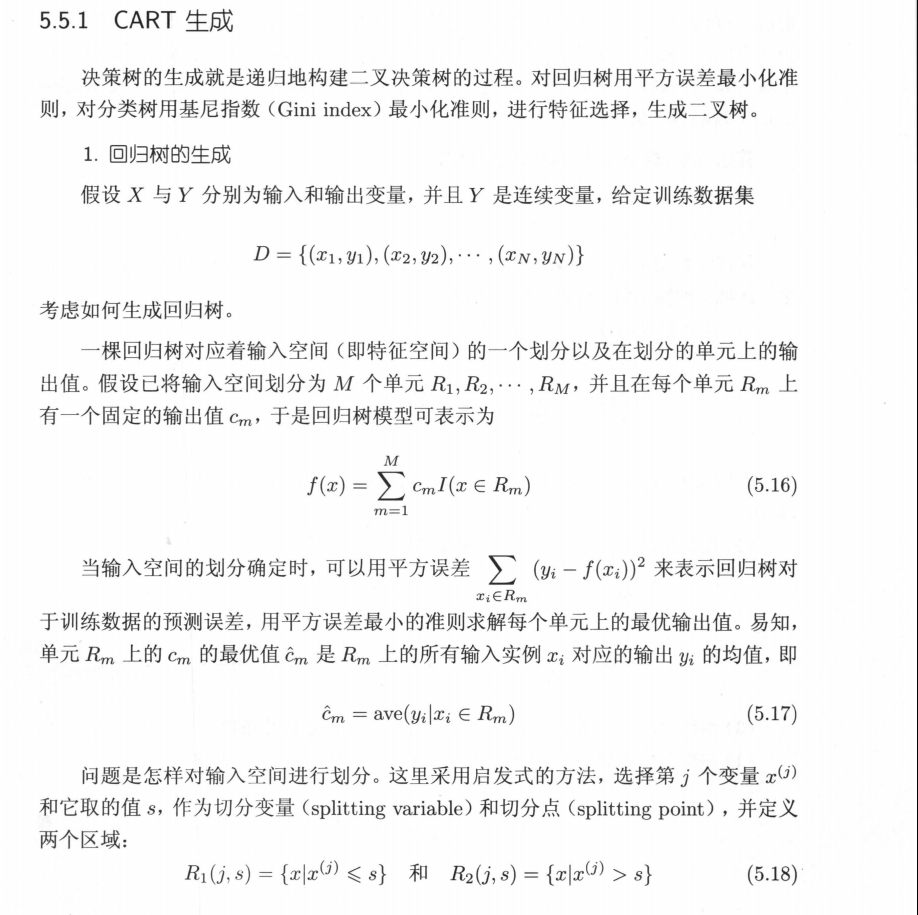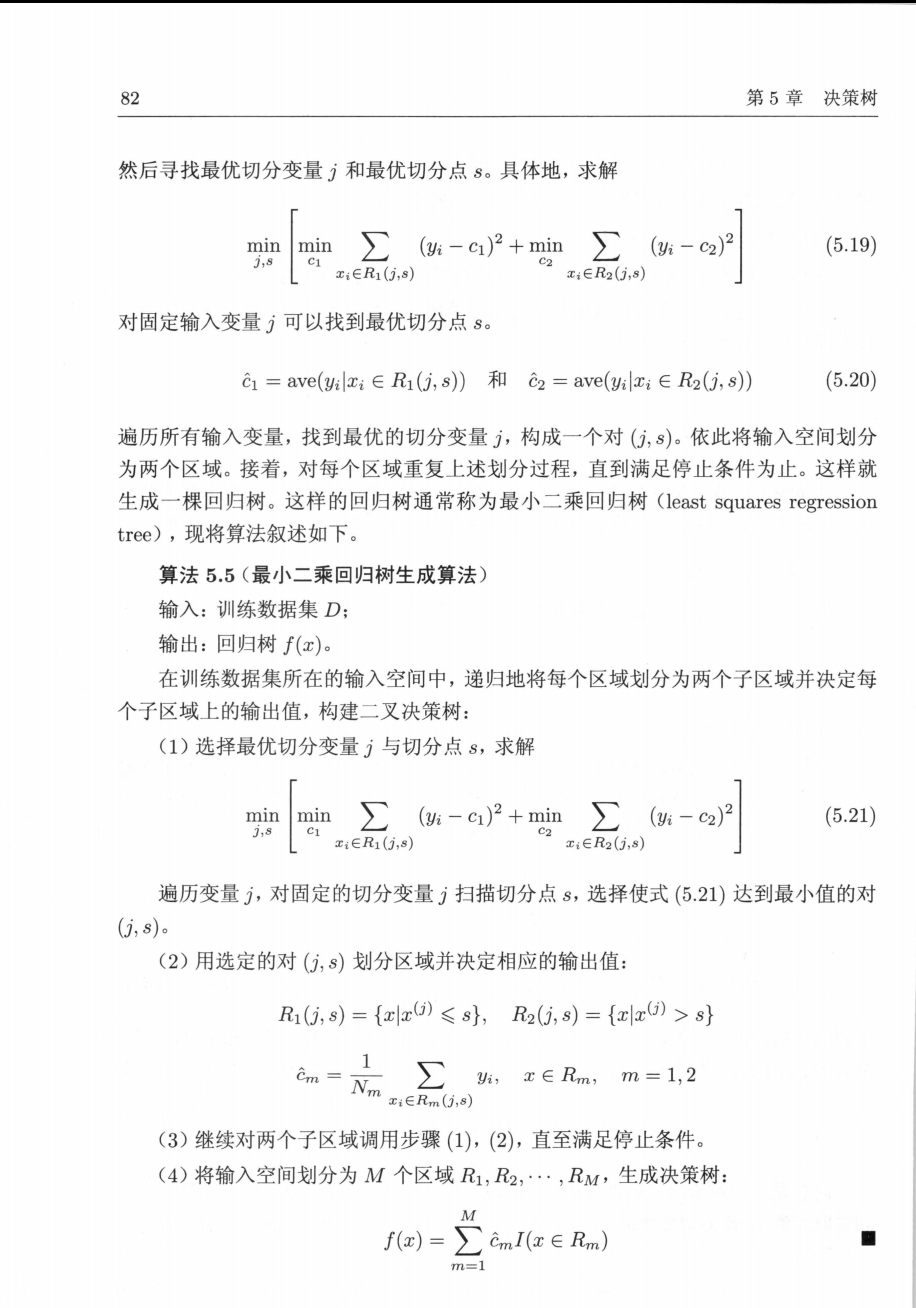

% 对数据进行8:2的划分
n = height(X);
% 确定随机种子，保证别人运行结果和我一致
rng(0);
% 随机打乱整数序列，生成随机不重复序列
% 随机获取80%的训练集，20%的测试集
idx = randperm(n);
% 计算训练数目
train_num = round(0.8*n);
% 获取训练集以及测试集
X_train = X(idx(1:train_num),:);
y_train = y(idx(1:train_num),:);
X_test = X(idx(train_num+1:end),:);
y_test = y(idx(train_num+1:end),:);

% 写子函数
% 寻找最优切分（j,s）
function [best_j,best_s,best_c1,best_c2,min_loss]=best_split(X,y)
    [m,n] = size(X);
    min_loss = inf; % 初始最小损失设为无穷大
    % 设置初始值
    best_j = -1; % 最优特征编号
    best_s = 0;  % 最优切分点
    best_c1 = 0; % 左边数据的平均值
    best_c2 = 0; % 右边数据的平均值

    % 遍历每个特征j
    for j=1:n
        feature = X(:,j);
        % 取出这个特征所有不重复的值为候选切分点
        vals = unique(feature); 

        % 遍历每个切分点s
        for s = 1:length(vals)
            s_val = vals(s);

            % 左右划分数据
            left = feature <= s_val;
            right = feature > s_val;

            % 如果左边没有数据或者右边没有数据的话跳过这个切分点
            if sum(left) == 0 || sum(right)==0
                continue;
            end

            % 左边和右边均有数据就分别计算平均值
            c1 = mean(y(left));
            c2 = mean(y(right));

            % 计算平方误差
            loss = sum((y(left)-c1).^2) + sum((y(right)-c2).^2);

            if loss < min_loss
                min_loss = loss;
                best_j = j;
                best_s = s_val;
                best_c1 = c1;
                best_c2 = c2;
            end
        end
    end
end

% 递归建树，完全生长
function tree = bulid_tree(X,y,depth,max_depth)
    % 停止条件、数据太少，树深度达到最大，所要划分的类标签几乎一样
    if length(y) <=5 || depth >= max_depth || var(y) < 1e-6
        tree.is_leaf = true;
        tree.val = mean(y);
        return;
    end

    % 找最优切分
    [j,s,c1,c2,~] = best_split(X,y);

    % 划分
    left_idx = X(:,j) <= s;
    right_idx = X(:,j) > s;

    % 递归
    tree.is_leaf = false;
    tree.j = j;
    tree.s = s;
    tree.c1 = c1;
    tree.c2 = c2;
    tree.left = bulid_tree(X(left_idx,:),y(left_idx),depth+1,max_depth);
    tree.right = bulid_tree(X(right_idx,:),y(right_idx,:),depth+1,max_depth);
end

% 生成一棵完全生长的树
tree = bulid_tree(X_train,y_train,0,100);

% 打印决策树
function print_tree(tree, depth)
    % 清晰版打印：中文 + 显示真实特征名(A2,A3,A8...)
    % 你的6个连续特征，顺序必须和你建X时一样！
    feature_names = {'A2','A3','A8','A11','A14','A15'};

    % 缩进（层级越深越靠右）
    indent = repmat('|  ', 1, depth);

    % ========== 打印当前节点 ==========
    fprintf('%s┌──────── 第 %d 层节点 ────────\n', indent, depth);
    fprintf('%s│ 是否叶子：%d  (1=是, 0=否)\n', indent, tree.is_leaf);

    if tree.is_leaf
        % 叶子节点：输出预测值
        fprintf('%s│ 预测值(val)：%.4f\n', indent, tree.val);
        if tree.val>=0.5
            indent = '+';
        else indent = '-';
        end
        fprintf('%s│ 判定结果：%s\n', indent);
    else
        % 内部节点：显示 特征名 + 阈值
        feat = feature_names{tree.j};
        fprintf('%s│ 分裂特征：j=%d → %s\n', indent, tree.j, feat);
        fprintf('%s│ 分裂阈值：%.4f\n', indent, tree.s);
        fprintf('%s│ 规则：%s ≤ %.2f → 左 | 否则 → 右\n', indent, feat, tree.s);
    end

    fprintf('%s└────────────────────────────\n', indent);

    % ========== 递归打印子树 ==========
    if ~tree.is_leaf
        print_tree(tree.left, depth+1);
        print_tree(tree.right, depth+1);
    end
end
print_tree(tree, 0)

┌──────── 第 0 层节点 ────────
│ 是否叶子：0  (1=是, 0=否)
│ 分裂特征：j=4 → A11
│ 分裂阈值：2.0000
│ 规则：A11 ≤ 2.00 → 左 | 否则 → 右
└────────────────────────────
|  ┌──────── 第 1 层节点 ────────
|  │ 是否叶子：0  (1=是, 0=否)
|  │ 分裂特征：j=3 → A8
|  │ 分裂阈值：1.2900
|  │ 规则：A8 ≤ 1.29 → 左 | 否则 → 右
|  └────────────────────────────
|  |  ┌──────── 第 2 层节点 ────────
|  |  │ 是否叶子：0  (1=是, 0=否)
|  |  │ 分裂特征：j=6 → A15
|  |  │ 分裂阈值：5552.0000
|  |  │ 规则：A15 ≤ 5552.00 → 左 | 否则 → 右
|  |  └────────────────────────────
|  |  |  ┌──────── 第 3 层节点 ────────
|  |  |  │ 是否叶子：0  (1=是, 0=否)
|  |  |  │ 分裂特征：j=6 → A15
|  |  |  │ 分裂阈值：501.0000
|  |  |  │ 规则：A15 ≤ 501.00 → 左 | 否则 → 右
|  |  |  └────────────────────────────
|  |  |  |  ┌──────── 第 4 层节点 ────────
|  |  |  |  │ 是否叶子：0  (1=是, 0=否)
|  |  |  |  │ 分裂特征：j=5 → A14
|  |  |  |  │ 分裂阈值：280.0000
|  |  |  |  │ 规则：A14 ≤ 280.00 → 左 | 否则 → 右
|  |  |  |  └────────────────────────────
|  |  |  |  |  ┌──────── 第 5 层节点 ────────
|  |  |  |  |  │ 是否叶子：0  (1=是, 0=否)
|  |  |  |  |  │ 分裂特征：j=2 → A3
|  |  |  

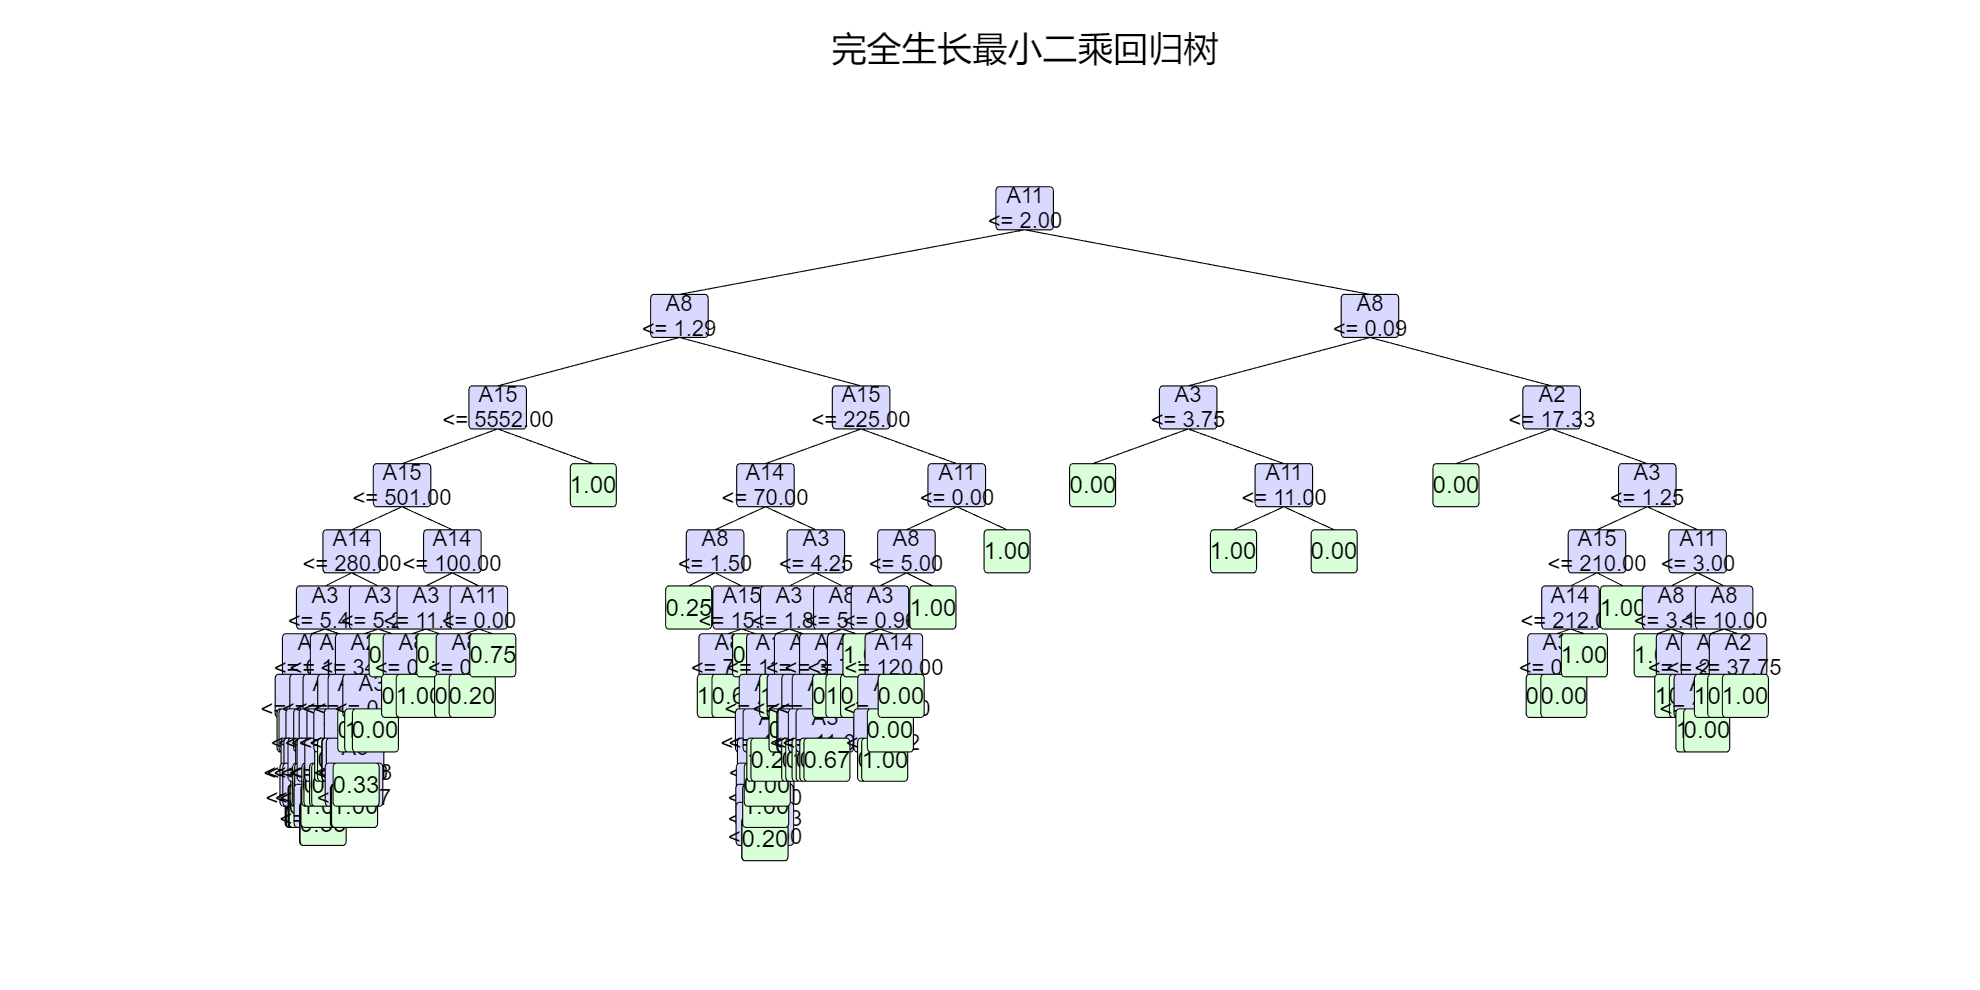

% 画出决策树
function plot_my_tree(tree, feature_names)
    % 输入参数：
    % tree：你生成的回归树结构体
    % feature_names：特征名称列表，比如 {'A2','A3','A8','A11','A14','A15'}

    figure('Color','white','Position',[100,100,1200,600]);
    hold on;
    axis off;
    title('完全生长最小二乘回归树','FontSize',16);
    
    % 递归画整棵树
    draw_tree(tree, 0, 0, 18, 4, feature_names);
end

function draw_tree(node, x, y, h_step, v_step, feature_names)
    % 叶子节点
    if node.is_leaf
        rectangle('Position',[x-1.2,y-0.8,2.4,1.6],...
            'Curvature',0.2,'FaceColor',[0.85 1 0.85]);
        text(x, y, sprintf('%.2f', node.val),...
             'HorizontalAlignment','center','FontSize',11);
        return;
    end
    
    % 内部节点：用你实际的特征名称显示
    feat_name = feature_names{node.j};  % 直接取列表里的名字
    node_str = sprintf('%s\n<= %.2f', feat_name, node.s);
    
    rectangle('Position',[x-1.5,y-0.8,3,1.6],...
        'Curvature',0.2,'FaceColor',[0.85 0.85 1]);
    text(x, y, node_str,...
         'HorizontalAlignment','center','FontSize',10);
    
    % 画左孩子
    line([x, x-h_step], [y-0.8, y-v_step+0.8], 'Color','black');
    draw_tree(node.left, x-h_step, y-v_step, h_step/1.9, v_step*0.85, feature_names);
    
    % 画右孩子
    line([x, x+h_step], [y-0.8, y-v_step+0.8], 'Color','black');
    draw_tree(node.right, x+h_step, y-v_step, h_step/1.9, v_step*0.85, feature_names);
end
% 定义特征名称列表，顺序和你取列的顺序一致
feature_names = {'A2','A3','A8','A11','A14','A15'};

% 生成树后调用画图函数
plot_my_tree(tree, feature_names);

% 编写预测函数
function y_pred = predict(tree,X)
    % 初始化预测结果，创建全为0的列向量
    y_pred = zeros(size(X,1),1);

    % 遍历每一个要预测的样本
    for i = 1:size(X,1)
        node = tree; 

        % 从根节点开始，直到走到叶子节点 
        while ~node.is_leaf
            if X(i,node.j) <= node.s
                node = node.left;
            else node = node.right;
            end
        end
        % 走到叶子节点
        if node.val>=0.5
            y_pred(i) = 1;
        else
            y_pred(i) = 0;
        end
    end
end
% 利用生成回归树预测y
% 训练集
y_train_pred = predict(tree,X_train);
% 计算训练集准确率
acc_train = mean(y_train_pred==y_train);
% 测试集
y_test_pred = predict(tree,X_test);
% 计算测试集准确率
acc_test = mean(y_test_pred==y_test);
fprintf("训练集准确率：%4f\n",acc_train);

训练集准确率：0.949343


fprintf("测试集准确率：%4f\n",acc_test);

测试集准确率：0.676692


% 由于训练集预测比测试集预测准确率相差较大，且训练集预测准确
% 典型的过拟合现象，需进行剪枝
%% ==================== 超高速 CART 剪枝（基于节点汇总统计量） ====================
% 适用：树已预存每个节点的样本索引（.indices），或通过 add_indices 添加后，
%       再调用 add_statistics 为每个节点计算 cnt, sum_y, sum_y2

%% 1. 为树添加样本索引（如果原始树没有）
function tree = add_indices_to_tree(tree, X, indices)
    if nargin < 3
        indices = (1:size(X,1))';
    end
    tree.indices = indices;
    if ~tree.is_leaf
        split_col = X(indices, tree.j);
        left_flag = split_col <= tree.s;
        right_flag = ~left_flag;
        left_idx = indices(left_flag);
        right_idx = indices(right_flag);
        tree.left = add_indices_to_tree(tree.left, X, left_idx);
        tree.right = add_indices_to_tree(tree.right, X, right_idx);
    end
end

%% 2. 为每个节点计算统计量 cnt, sum_y, sum_y2（只需调用一次）
function tree = add_statistics(tree, y)
    if tree.is_leaf
        y_sub = y(tree.indices);
        tree.cnt = length(y_sub);
        tree.sum_y = sum(y_sub);
        tree.sum_y2 = sum(y_sub.^2);
    else
        tree.left = add_statistics(tree.left, y);
        tree.right = add_statistics(tree.right, y);
        % 内部节点的统计量 = 左右子节点之和
        tree.cnt = tree.left.cnt + tree.right.cnt;
        tree.sum_y = tree.left.sum_y + tree.right.sum_y;
        tree.sum_y2 = tree.left.sum_y2 + tree.right.sum_y2;
    end
end

%% 3. 计算给定节点的 R(t)（自身作为叶子的损失）
function Rt = calc_Rt(node)
    % R(t) = sum(y^2) - (sum(y))^2 / n
    Rt = node.sum_y2 - (node.sum_y^2) / node.cnt;
end

%% 4. 后序遍历计算每个内部节点的 loss_subtree 和 leaves_count（常数时间）
function node = update_subtree_stats(node)
    if node.is_leaf
        node.loss_subtree = calc_Rt(node);
        node.leaves_count = 1;
    else
        node.left = update_subtree_stats(node.left);
        node.right = update_subtree_stats(node.right);
        node.loss_subtree = node.left.loss_subtree + node.right.loss_subtree;
        node.leaves_count = node.left.leaves_count + node.right.leaves_count;
    end
end

%% 5. 计算所有内部节点的 g(t) 并找出最小值（同时返回路径信息）
function [min_g, best_node, parent, is_left] = find_min_g_fast(node, curr_parent, is_left_child)
    if node.is_leaf
        min_g = inf;
        best_node = [];
        parent = [];
        is_left = [];
        return;
    end
    
    % 当前节点的 g(t)
    Rt = calc_Rt(node);
    g = (Rt - node.loss_subtree) / (node.leaves_count - 1);
    min_g = g;
    best_node = node;
    parent = curr_parent;
    is_left = is_left_child;
    
    % 递归左右子树
    [gl, nl, pl, il] = find_min_g_fast(node.left, node, true);
    [gr, nr, pr, ir] = find_min_g_fast(node.right, node, false);
    
    if gl < min_g
        min_g = gl; best_node = nl; parent = pl; is_left = il;
    end
    if gr < min_g
        min_g = gr; best_node = nr; parent = pr; is_left = ir;
    end
end

%% 6. 将指定内部节点替换为叶子（常数时间更新其祖先）
% 注意：剪枝后，该节点变为叶子，其 loss_subtree 改为自身的 Rt，leaves_count=1
% 同时需要向上更新所有祖先的 loss_subtree 和 leaves_count
function tree = prune_node(tree_root, target_node, parent, is_left)
    % 创建新叶子（保留目标节点的统计量，以便父节点正确聚合）
    new_leaf = target_node;
    new_leaf.is_leaf = true;
    new_leaf.val = target_node.sum_y / target_node.cnt;   % 该子集的均值
    % 叶子节点的 loss_subtree 就是其 Rt
    new_leaf.loss_subtree = calc_Rt(target_node);
    new_leaf.leaves_count = 1;
    
    % 替换
    if isempty(parent)
        tree_root = new_leaf;
    else
        if is_left
            parent.left = new_leaf;
        else
            parent.right = new_leaf;
        end
    end
    
    % 向上更新受影响的祖先节点（从 parent 开始一直向上到根）
    % 但 parent 可能已经被局部变量引用，我们需要重新沿树路径更新。
    % 简便方法：从根重新调用 update_subtree_stats，但只更新必要的路径？
    % 鉴于节点数少，直接整树重新统计（O(NodeCount)）即可，足够快。
    % 为了代码简洁，这里调用整树更新。
    tree_root = update_subtree_stats(tree_root);
    
    if nargout > 0
        tree = tree_root;
    end
end

%% 7. 主剪枝函数（超高速）
function tree_pruned = cart_prune_ultrafast(tree, X, y)
    % 步骤0：保证节点有 .indices（如果没有，则添加）
    if ~isfield(tree, 'indices')
        tree = add_indices_to_tree(tree, X);
    end
    % 步骤1：添加统计量 cnt, sum_y, sum_y2
    tree = add_statistics(tree, y);
    % 步骤2：初始计算 loss_subtree 和 leaves_count
    tree = update_subtree_stats(tree);
    
    tree_pruned = tree;
    
    while true
        % 寻找最小 g(t) 的内部节点
        [min_g, best_node, parent, is_left] = find_min_g_fast(tree_pruned, [], false);
        if isempty(best_node)
            break;
        end
        
        % 剪掉该节点（同时自动更新整树统计量）
        tree_pruned = prune_node(tree_pruned, best_node, parent, is_left);
        
        % 如果只剩下一个叶子，停止
        if tree_pruned.is_leaf
            break;
        end
    end
end

% ====================== 执行剪枝 ======================
% tree_pruned = cart_prune_ultrafast(tree, X_train, y_train);
% 比较剪枝前后的效果
% y_train_pred_p = predict(tree_pruned, X_train);
% y_test_pred_p = predict(tree_pruned, X_test);
% acc_train_p = mean(y_train_pred_p==y_train);
% acc_test_p = mean(y_test_pred_p==y_test);
% fprintf("剪枝后训练集准确率：%4f\n",acc_train_p);
% fprintf("剪枝后训练集准确率：%4f\n",acc_test_p);
% % 画出剪枝后的回归树
% plot_my_tree(tree_pruned, feature_names);
% title('剪枝后的最小二乘回归树','FontSize',16);
